# Exercise 1 a) 

fun = @(x) 2 ./ (1 + x.^2);
a = 0; b = 1;
n = 10;
h = (b - a) / n;
x_vals = a:h:b;

area_trap = h/2 * (fun(a) + 2*sum(fun(x_vals(2:end-1))) + fun(b));
fprintf('Approximate integral: %.8f\n', area_trap);

Approximate integral: 1.56996299


## Exercise 1 b) 

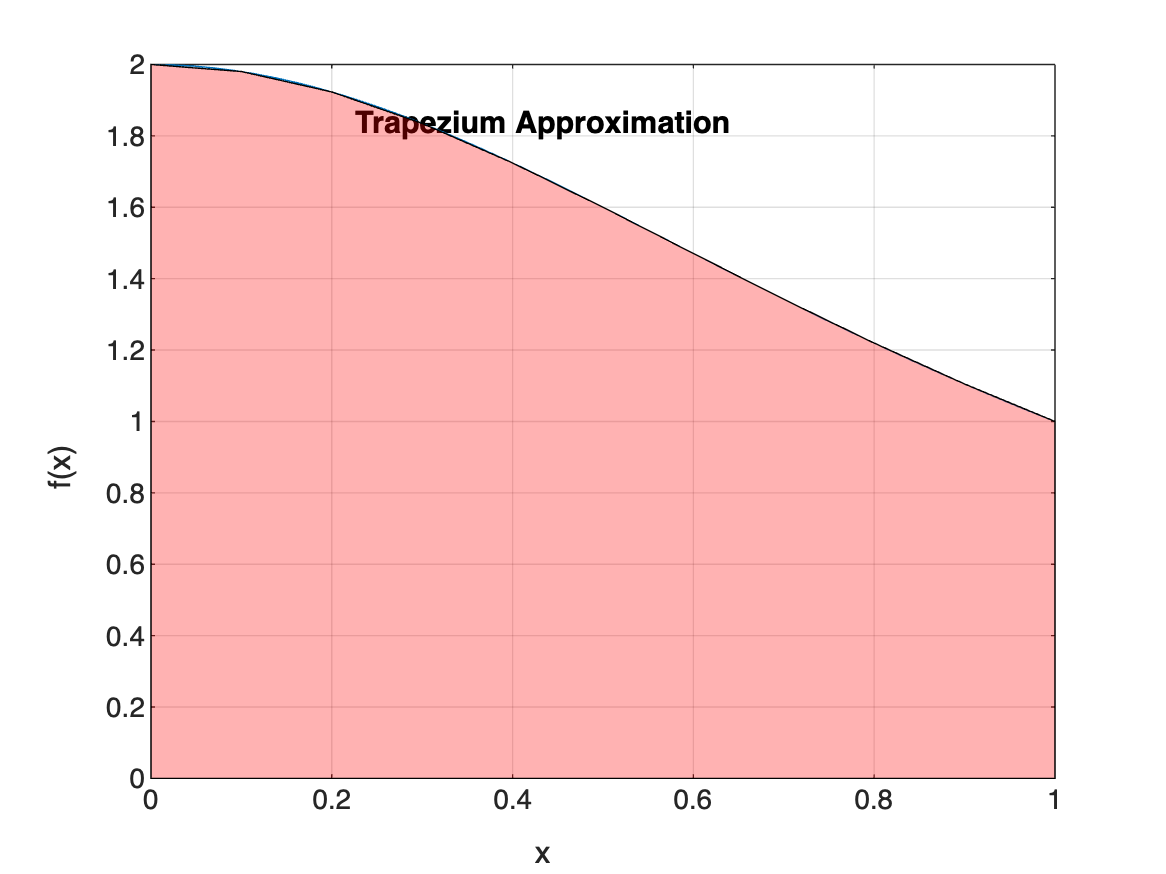

figure;
fplot(fun, [a, b]); hold on;
fill([a, x_vals, b], [0, fun(x_vals), 0], 'r', 'FaceAlpha', 0.3);
title('Trapezium Approximation');
xlabel('x'); ylabel('f(x)');
grid on;

## Exercise 1 c) 

if mod(n, 2) ~= 0
    n = n + 1;
end
h = (b - a) / n;
x_vals = a:h:b;

area_simp = (h/3) * ( ...
    fun(x_vals(1)) + ...
    4 * sum(fun(x_vals(2:2:end-1))) + ...
    2 * sum(fun(x_vals(3:2:end-2))) + ...
    fun(x_vals(end)) ...
);
fprintf('Approximate integral (Simpson): %.8f\n', area_simp);

Approximate integral (Simpson): 1.57079631


## Exercise 2 

f2 = @(x, y) log(x + 2*y);
x1 = 1; x2 = 1.5;
y1 = 1.4; y2 = 2;

corners = f2(x1,y1) + f2(x1,y2) + f2(x2,y1) + f2(x2,y2);
edges = 2 * (f2((x1+x2)/2, y1) + f2((x1+x2)/2, y2) + f2(x1, (y1+y2)/2) + f2(x2, (y1+y2)/2));
center = 4 * f2((x1+x2)/2, (y1+y2)/2);

I2 = ((x2 - x1)*(y2 - y1)/16) * (corners + edges + center);
fprintf('Estimated double integral: %.6f\n', I2);

Estimated double integral: 0.459578


## Exercise 3 

r = 110;
p = 75;

C = (60 * r) / (r^2 - p^2);

f = @(x) sqrt(1 - (p/r)^2 * sin(x));

trapezium_integral = @(n) ...
    (2*pi / n) * (0.5*f(0) + sum(f((2*pi/n)*(1:n-1))) + 0.5*f(2*pi));

n1 = 10;
n2 = 100;

I1 = trapezium_integral(n1);
I2 = trapezium_integral(n2);

H1 = C * I1;
H2 = C * I2;

fprintf('n = %d, Result: %.6f\n', n1, H1);

n = 10, Result: 6.313124


fprintf('n = %d, Result: %.6f\n', n2, H2);

n = 100, Result: 6.313124


## Exercise 4 

fx = @(x) x .* log(x);
true_integral = integral(fx, 1, 2);
for k = 1:100
    x_pts = linspace(1, 2, k + 1);
    y_pts = fx(x_pts);
    approx = trapz(x_pts, y_pts);
    if abs(approx - true_integral) < 0.001
        break;
    end
end
fprintf('Smallest n with error < 0.001: %d  → Result: %.10f\n', k, approx);

Smallest n with error < 0.001: 8  → Result: 0.6371966429


## Exercise 5 

g = @(x) 1 ./ (4 + sin(20*x));
a = 0; b = pi;
n10 = 10; n30 = 30;

simpson_calc = @(func, a, b, n) ...
    (b - a) / (3 * n) * ( ...
    func(a) + ...
    4 * sum(func(a + (1:2:n-1)*(b-a)/n)) + ...
    2 * sum(func(a + (2:2:n-2)*(b-a)/n)) + ...
    func(b) ...
);

res_n10 = simpson_calc(g, a, b, n10);
res_n30 = simpson_calc(g, a, b, n30);

fprintf('Simpson estimate (n=10): %.8f\n', res_n10);

Simpson estimate (n=10): 0.78539816


fprintf('Simpson estimate (n=30): %.8f\n', res_n30);

Simpson estimate (n=30): 0.81114892


## Exercise 6 

gauss_fun = @(t) exp(-t.^2);
true_erf = 0.520499876;
simpson_erf = @(upper, n) (2/sqrt(pi)) * simpson_calc(gauss_fun, 0, upper, n);

erf4 = simpson_erf(0.5, 4);
erf10 = simpson_erf(0.5, 10);

fprintf('Erf Simpson n=4:  %.9f | Error: %.9f\n', erf4, abs(erf4 - true_erf));

Erf Simpson n=4:  0.520505930 | Error: 0.000006054


fprintf('Erf Simpson n=10: %.9f | Error: %.9f\n', erf10, abs(erf10 - true_erf));

Erf Simpson n=10: 0.520500031 | Error: 0.000000155
